## Data Collection and Processing

First, we need to acquire the dataset and perform initial preprocessing like resizing, normalization, and augmentation.

% Define the paths to dataset
dataFolder = 'dataset';
% Define the paths to your training and testing directories
trainDir = fullfile(dataFolder, 'train');
testDir = fullfile(dataFolder, 'test');

% Create the imageDatastores and specify the ReadFcn for normalization
trainDatastore = imageDatastore(trainDir, 'IncludeSubfolders', true, 'LabelSource', 'foldernames', ...
    'ReadFcn', @(x) im2double(imread(x)));
testDatastore = imageDatastore(testDir, 'IncludeSubfolders', true, 'LabelSource', 'foldernames', ...
    'ReadFcn', @(x) im2double(imread(x)));

Next, we'll define the Data Augmentation and create 'augmentedDatastore'

% Define augmentation options
augmenter = imageDataAugmenter(...
    'RandRotation', [-30, 30], ...
    'RandXTranslation', [-3, 3], ...
    'RandYTranslation', [-3, 3], ...
    'RandXScale', [0.8, 1.2], ...
    'RandYScale', [0.8, 1.2]);

% Using 48x48 grayscale images from CK+ dataset
imageSize = [48 48 1];  % Change to [48 48 3] if using color images

% Create augmented image datastore
trainAugmentedDatastore = augmentedImageDatastore(imageSize, trainDatastore, 'DataAugmentation', augmenter);


## Model Design and Training

Design a simple CNN architecture and train it using the processed dataset.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:06 |       13.28% |       34.25% |       2.4612 |       2.4538 |          0.0100 |
|       5 |          30 |       00:00:17 |       95.31% |       97.96% |       0.1676 |       0.1255 |          0.0100 |
|       8 |          50 |       00:00:22 |      100.00% |              |       0.0397 |              |          0.0100 |
|       9 |          60 |       00:00:25 |      100.00% |      100.00% |       0.0281 |   

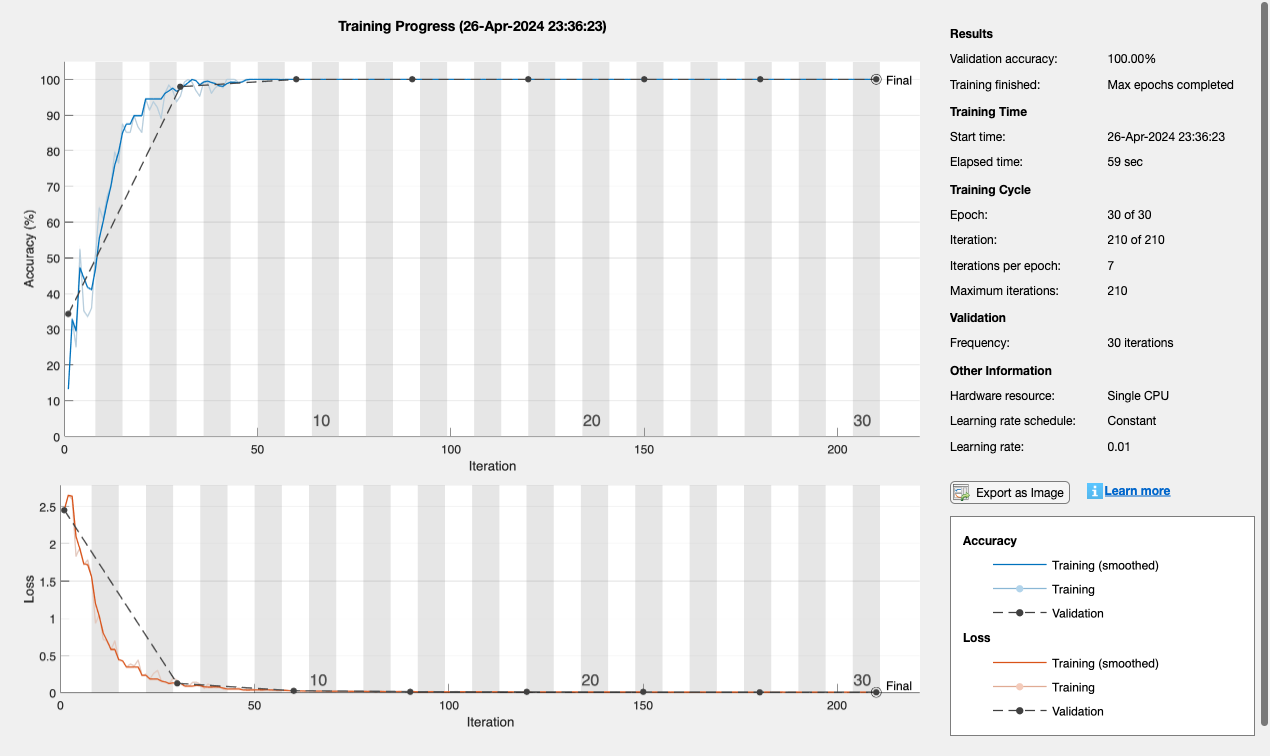

layers = [
    imageInputLayer(imageSize)

    convolution2dLayer(3, 8, 'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2, 'Stride', 2)

    convolution2dLayer(3, 16, 'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2, 'Stride', 2)

    convolution2dLayer(3, 32, 'Padding','same')
    batchNormalizationLayer
    reluLayer

    fullyConnectedLayer(7) % 7 neurons for the 7 classes in the data set
    softmaxLayer
    classificationLayer];

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',30, ...
    'Shuffle','every-epoch', ...
    'ValidationData',testDatastore, ...
    'ValidationFrequency',30, ...
    'Verbose',true, ...
    'Plots','training-progress');

net = trainNetwork(trainDatastore, layers, options);

## Model Evaluation

Evaluate the model using metrics such as accuracy, precision, recall, and F1-score.

YPred = classify(net, testDatastore);
YTest = testDatastore.Labels;

% Calculate accuracy
accuracy = sum(YPred == YTest)/numel(YTest);
disp(['Accuracy: ', num2str(accuracy)])

Accuracy: 1



% Calculate precision, recall, and F1-score
confMat = confusionmat(YTest, YPred);
precision = diag(confMat)./sum(confMat, 2);
recall = diag(confMat)./sum(confMat, 1)';
f1Scores = 2*(precision.*recall)./(precision + recall);

disp(table(unique(YTest), precision, recall, f1Scores, 'VariableNames', {'Expression', 'Precision', 'Recall', 'F1Score'}))

    Expression    Precision    Recall    F1Score
    __________    _________    ______    _______

     anger            1          1          1   
     contempt         1          1          1   
     disgust          1          1          1   
     fear             1          1          1   
     happy            1          1          1   
     sadness          1          1          1   
     surprise         1          1          1   

